## REGULARIZATION METHODS

## 1. Tikhonov Regularization (iterative, for full images)

## 2. Truncated SVD (TSVD) (spectral, for small patches)

## 3. NSIT + Morozov Discrepancy Principle (iterative, for full images)

clear; clc; close all;

## Part 1 : Common Set Up

## 1.1 Load Image

image_path = '296059.jpg';

img = imread(image_path);

% Convert to grayscale
if ndims(img) == 3
    img = mean(double(img), 3);
else
    img = double(img);
end

% Normalize
x_true = img / max(img(:));

fprintf('Image shape: %d x %d\n', size(x_true, 1), size(x_true, 2));

Image shape: 321 x 481


#### 1.2 Gaussian Blur Kernel

kernel_size = 9;
sigma = 2.0;

half_size = floor(kernel_size / 2);
[xx, yy] = meshgrid(-half_size:half_size, -half_size:half_size);
kernel = exp(-(xx.^2 + yy.^2) / (2 * sigma^2));
kernel = kernel / sum(kernel(:));

#### 1.3 Forward Model: y = Ax + noise

noise_std = 0.01;

% Apply blur (forward operator A)
Ax = imfilter(x_true, kernel, 'symmetric', 'same');

% Add Gaussian noise
eps = noise_std * randn(size(Ax));
y = Ax + eps;

% Noise level (for Morozov)
delta = norm(eps(:));
fprintf('Noise level delta = %.4f\n', delta);

Noise level delta = 3.9268


## PART 2: TIKHONOV REGULARIZATION (Full Image)

fprintf('\n--- TIKHONOV REGULARIZATION ---\n');


--- TIKHONOV REGULARIZATION ---


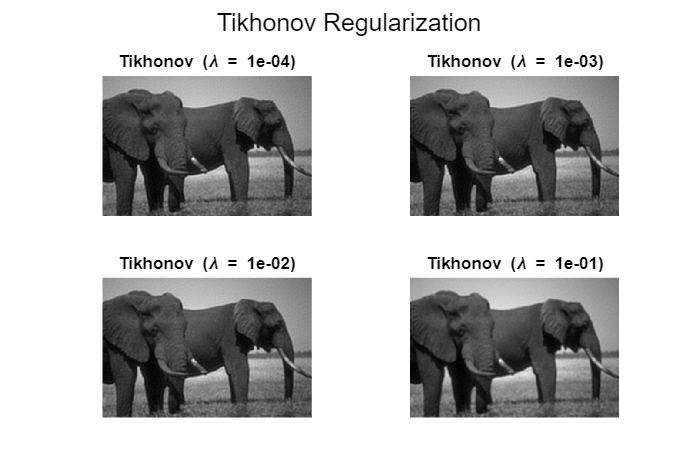

lambda = 1e-04 : Relative error = 0.0864
lambda = 1e-03 : Relative error = 0.0865
lambda = 1e-02 : Relative error = 0.0873
lambda = 1e-01 : Relative error = 0.1282



lambdas = [1e-4, 1e-3, 1e-2, 1e-1];

figure('Position', [100, 100, 1200, 800]);
sgtitle('Tikhonov Regularization');

for i = 1:length(lambdas)
    lam = lambdas(i);
    
    % Apply Tikhonov
    x_tik = tikhonov_reconstruction(y, kernel, lam, 200, 0.1);
    
    % Compute error
    err = norm(x_tik(:) - x_true(:)) / norm(x_true(:));
    fprintf('lambda = %.0e : Relative error = %.4f\n', lam, err);
    
    subplot(2, 2, i);
    imagesc(x_tik);
    colormap gray;
    axis image off;
    title(sprintf('Tikhonov (\\lambda = %.0e)', lam));
end

## PART 3: TRUNCATED SVD (16x16 Patch Only)

fprintf('\n--- TRUNCATED SVD (16x16 PATCH) ---\n');


--- TRUNCATED SVD (16x16 PATCH) ---



% Extract 16x16 patch (TSVD requires explicit matrix A)
patch = x_true(101:116, 101:116);
patch = patch / max(patch(:));
n_patch = size(patch, 1);

% Build explicit blur matrix for patch
A_matrix = build_blur_matrix(kernel, n_patch);

% Forward model on patch
Ax_patch = imfilter(patch, kernel, 'symmetric', 'same');
eps_patch = noise_std * randn(size(Ax_patch));
y_patch = Ax_patch + eps_patch;

% SVD of A
[U, S_mat, V] = svd(A_matrix, 'econ');
S = diag(S_mat);

fprintf('Condition number of A: %.2e\n', S(1)/S(end));

Condition number of A: 5.87e+07


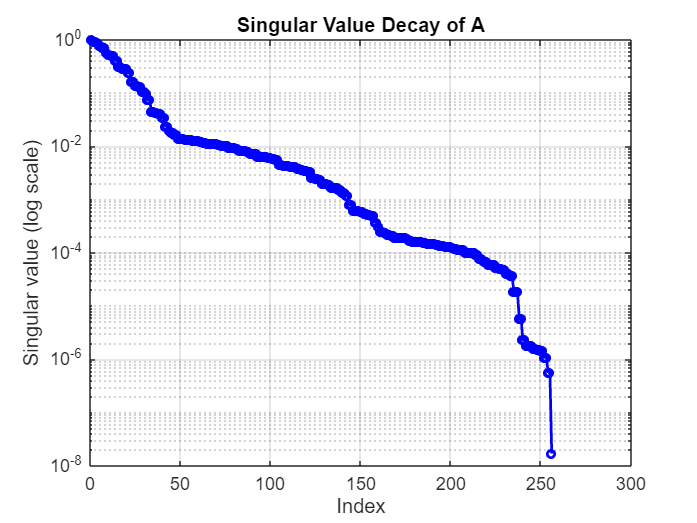


% Vectorize
x_vec = patch(:);
y_vec = y_patch(:);

% Plot singular value decay
figure;
semilogy(S, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Index');
ylabel('Singular value (log scale)');
title('Singular Value Decay of A');
grid on;

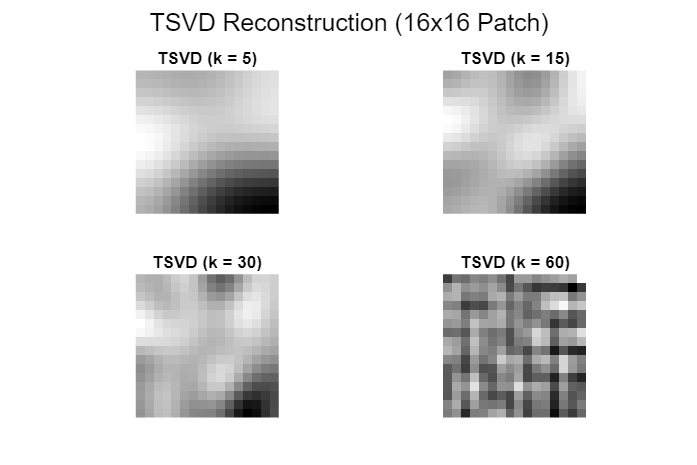

k =  5 : Relative error = 0.0809
k = 15 : Relative error = 0.0706
k = 30 : Relative error = 0.0671
k = 60 : Relative error = 0.2490



% TSVD with different k values
ks = [5, 15, 30, 60];

figure('Position', [100, 100, 1200, 800]);
sgtitle('TSVD Reconstruction (16x16 Patch)');

for i = 1:length(ks)
    k = ks(i);
    
    % Apply TSVD
    x_tsvd = tsvd_reconstruction(U, S, V, y_vec, k);
    x_tsvd_img = reshape(x_tsvd, [n_patch, n_patch]);
    
    % Compute error
    err = norm(x_tsvd - x_vec) / norm(x_vec);
    fprintf('k = %2d : Relative error = %.4f\n', k, err);
    
    subplot(2, 2, i);
    imagesc(x_tsvd_img);
    colormap gray;
    axis image off;
    title(sprintf('TSVD (k = %d)', k));
end

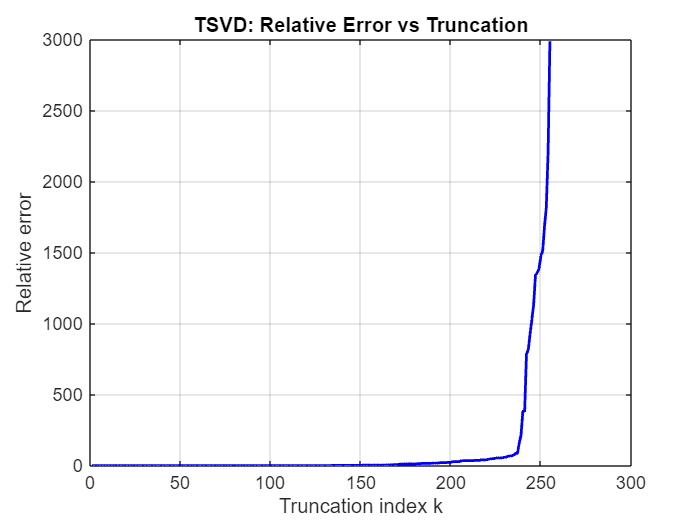


% Error vs truncation index
errors_tsvd = zeros(length(S)-1, 1);
for k = 1:length(S)-1
    x_k = tsvd_reconstruction(U, S, V, y_vec, k);
    errors_tsvd(k) = norm(x_k - x_vec) / norm(x_vec);
end

figure;
plot(1:length(errors_tsvd), errors_tsvd, 'b-', 'LineWidth', 1.5);
xlabel('Truncation index k');
ylabel('Relative error');
title('TSVD: Relative Error vs Truncation');
grid on;

## PART 4: NSIT + MOROZOV DISCREPANCY (Full Image)

fprintf('\n--- NSIT + MOROZOV DISCREPANCY ---\n');


--- NSIT + MOROZOV DISCREPANCY ---



% NSIT parameters
n_iter_max = 50;
alpha0 = 1e-1;
q = 0.7;        % Decay factor
tau = 1.05;     % Morozov safety factor

% Run NSIT
[x_nsit, residuals, errors_nsit, stop_iter] = nsit_morozov(y, x_true, kernel, ...
    delta, alpha0, q, tau, n_iter_max);

Iter 01 | alpha=1.00e-01 | residual=1.665e+01 | error=0.1359
Iter 02 | alpha=7.00e-02 | residual=4.222e+00 | error=0.0904
Iter 03 | alpha=4.90e-02 | residual=3.912e+00 | error=0.0883
Morozov discrepancy satisfied at iteration 3



fprintf('Stopped at iteration %d\n', stop_iter);

Stopped at iteration 3


fprintf('Final relative error: %.4f\n', errors_nsit(end));

Final relative error: 0.0883


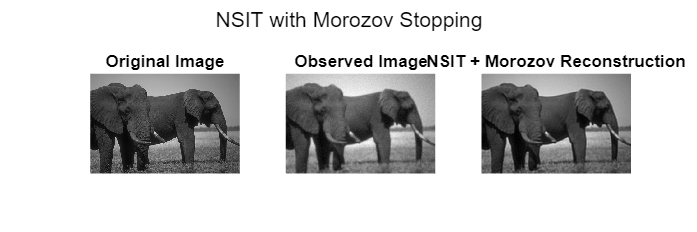


% Visualization
figure('Position', [100, 100, 1200, 400]);

subplot(1, 3, 1);
imagesc(x_true);
colormap gray;
axis image off;
title('Original Image');

subplot(1, 3, 2);
imagesc(y);
colormap gray;
axis image off;
title('Observed Image');

subplot(1, 3, 3);
imagesc(x_nsit);
colormap gray;
axis image off;
title('NSIT + Morozov Reconstruction');

sgtitle('NSIT with Morozov Stopping');

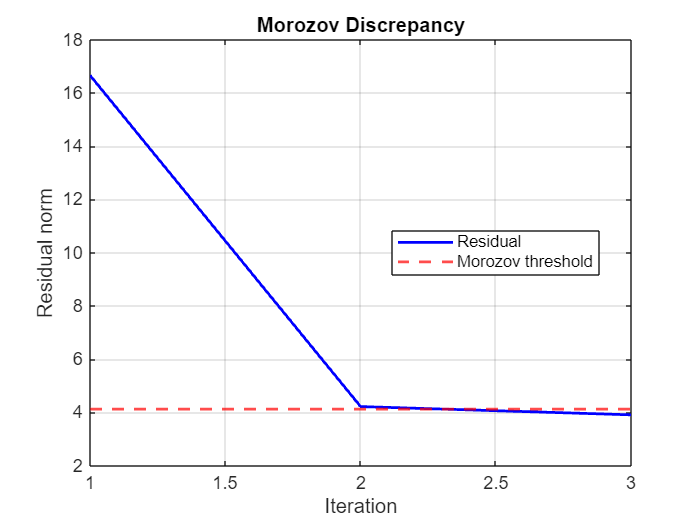


% Residual plot
figure;
plot(1:length(residuals), residuals, 'b-', 'LineWidth', 1.5);
hold on;
yline(tau * delta, 'r--', 'LineWidth', 1.5);
hold off;
xlabel('Iteration');
ylabel('Residual norm');
title('Morozov Discrepancy');
legend('Residual', 'Morozov threshold', 'Location', 'best');
grid on;

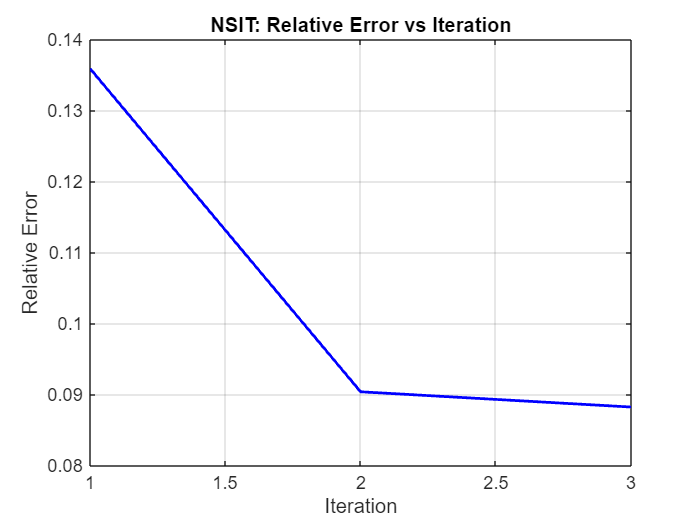


% Error plot
figure;
plot(1:length(errors_nsit), errors_nsit, 'b-', 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Relative Error');
title('NSIT: Relative Error vs Iteration');
grid on;

## PART 5: COMPARISON OF ALL METHODS

fprintf('\n--- FINAL COMPARISON ---\n');


--- FINAL COMPARISON ---



% Best Tikhonov (lambda = 1e-2)
x_tik_best = tikhonov_reconstruction(y, kernel, 1e-2, 200, 0.1);
err_tik = norm(x_tik_best(:) - x_true(:)) / norm(x_true(:));

% NSIT error
err_nsit = errors_nsit(end);

fprintf('Tikhonov (lambda=1e-2): Relative error = %.4f\n', err_tik);

Tikhonov (lambda=1e-2): Relative error = 0.0873


fprintf('NSIT + Morozov:        Relative error = %.4f\n', err_nsit);

NSIT + Morozov:        Relative error = 0.0883


## FUNCTION DEFINITIONS

## Function: Forward Operator A (Blur)

function Ax = A_op(x, kernel)
Ax = imfilter(x, kernel, 'symmetric', 'same');
end

## Function: Adjoint Operator A^T (Correlation)

function ATx = AT_op(x, kernel)
% Adjoint of convolution = correlation = convolution with flipped kernel
kernel_flipped = rot90(kernel, 2);  % Flip both dimensions
ATx = imfilter(x, kernel_flipped, 'symmetric', 'same');
end

## Function: Tikhonov Regularization (Gradient Descent)

function x_rec = tikhonov_reconstruction(y, kernel, lam, n_iter, step)
% Solves: min ||Ax - y||^2 + lambda*||x||^2
% via gradient descent
%
% Inputs:
%   y      - Observed image
%   kernel - Blur kernel
%   lam    - Regularization parameter
%   n_iter - Number of iterations
%   step   - Step size (learning rate)
%
% Output:
%   x_rec  - Reconstructed image

x_rec = zeros(size(y));

for iter = 1:n_iter
    % Gradient: A^T(Ax - y) + lambda*x
    residual = A_op(x_rec, kernel) - y;
    grad = AT_op(residual, kernel) + lam * x_rec;
    
    % Gradient descent step
    x_rec = x_rec - step * grad;
end
end

## Function: Build Explicit Blur Matrix (for small patches only)

function A = build_blur_matrix(kernel, n)
% Builds explicit N x N blur matrix where N = n*n
% Only feasible for small n (e.g., n=16)

N = n * n;
A = zeros(N, N);

for i = 1:N
    % Create basis image with single 1
    basis = zeros(n, n);
    basis(i) = 1.0;
    
    % Apply blur
    blurred = imfilter(basis, kernel, 'symmetric', 'same');
    
    % Store as column
    A(:, i) = blurred(:);
end
end

## Function: Truncated SVD Reconstruction

function x_rec = tsvd_reconstruction(U, S, V, y_vec, k)
% TSVD reconstruction using first k singular values

% Inputs:
%   U, S, V - SVD components (S is vector of singular values)
%   y_vec   - Observed data (vectorized)
%   k       - Truncation index

% Output:
%   x_rec   - Reconstructed signal (vectorized)

Uk = U(:, 1:k);
Sk = S(1:k);
Vk = V(:, 1:k);

% x = V_k * S_k^(-1) * U_k^T * y
x_rec = Vk * (Uk' * y_vec ./ Sk);
end

## Function: Inner Solver for NSIT

function z = solve_inner(rhs, kernel, alpha, n_inner, step)
% Solves: (A^T A + alpha*I) z = rhs
% via gradient descent

z = zeros(size(rhs));

for iter = 1:n_inner
    % Gradient: A^T A z + alpha*z - rhs
    grad = AT_op(A_op(z, kernel), kernel) + alpha * z - rhs;
    z = z - step * grad;
end
end

## Function: NSIT with Morozov Discrepancy Principle

function [x_rec, residuals, errors, stop_iter] = nsit_morozov(y, x_true, kernel, ...
    delta, alpha0, q, tau, n_iter_max)
% Non-Stationary Iterated Tikhonov with Morozov stopping

% Inputs:
%   y         - Observed image
%   x_true    - True image (for error computation)
%   kernel    - Blur kernel
%   delta     - Noise level ||epsilon||
%   alpha0    - Initial regularization parameter
%   q         - Decay factor (0 < q < 1)
%   tau       - Morozov safety factor (typically 1.0-1.1)
%   n_iter_max- Maximum iterations
% 
% Outputs:
%   x_rec     - Reconstructed image
%   residuals - Residual norms at each iteration
%   errors    - Relative errors at each iteration
%   stop_iter - Iteration where stopped

x_rec = zeros(size(y));
residuals = [];
errors = [];
stop_iter = n_iter_max;

for n = 1:n_iter_max
    % Decaying regularization parameter
    alpha_n = alpha0 * (q ^ (n-1));
    
    % Compute residual
    r = y - A_op(x_rec, kernel);
    rhs = AT_op(r, kernel);
    
    % Solve inner problem
    update = solve_inner(rhs, kernel, alpha_n, 20, 0.2);
    x_rec = x_rec + update;
    
    % Compute residual norm
    res_norm = norm(A_op(x_rec, kernel) - y, 'fro');
    residuals = [residuals; res_norm];
    
    % Compute error (if true solution known)
    err = norm(x_rec(:) - x_true(:)) / norm(x_true(:));
    errors = [errors; err];
    
    fprintf('Iter %02d | alpha=%.2e | residual=%.3e | error=%.4f\n', ...
        n, alpha_n, res_norm, err);
    
    % Check Morozov stopping criterion
    if res_norm <= tau * delta
        fprintf('Morozov discrepancy satisfied at iteration %d\n', n);
        stop_iter = n;
        break;
    end
end
end